# **Lab 2:  Spectral analysis and Detection theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco (Flux 7.076)

Assistants: Yizhou Huang, Luan Fiorio, Agata Barbagini, Xueting Li

**Students (Name + IDs): Yuncheng Yuan + 1778307, Wei Zheng + 1886061, Sizhuo Yao + 1895591**

**Group #: Group 6**

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 2-3 students, which must register on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide.**

`•`**Sometimes, runing the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Canvas.

`•`In case of problems, the labs can alternatively be submitted by emailing the lab assistants. The email address are available on Canvas.

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available on Canvas.

`•`If plagiarism is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure that all the text is readable. Below some useful commandsfor these purposes:

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

Please submit this lab on Canvas by **07/04/2023**

## Introduction 

In this lab, we will analyze the random signal obtained from an electroencelographic (EEG) measurement using spectral estimation techniques. In a nutshell, during an EEG acquistion, multiple electrodes are located on a subject's scalp to monitor the electrical activity occurring from various parts of the brain. For studying sleep, EEG analysis has become particularly popular.

One of the most widely used method to analyze EEG data is to decompose the signal into functionally distinct frequency bands, such as delta (0.5–4 Hz), theta (4–8 Hz), alpha (8–12 Hz), beta (12–30 Hz), and gamma (30–100 Hz).

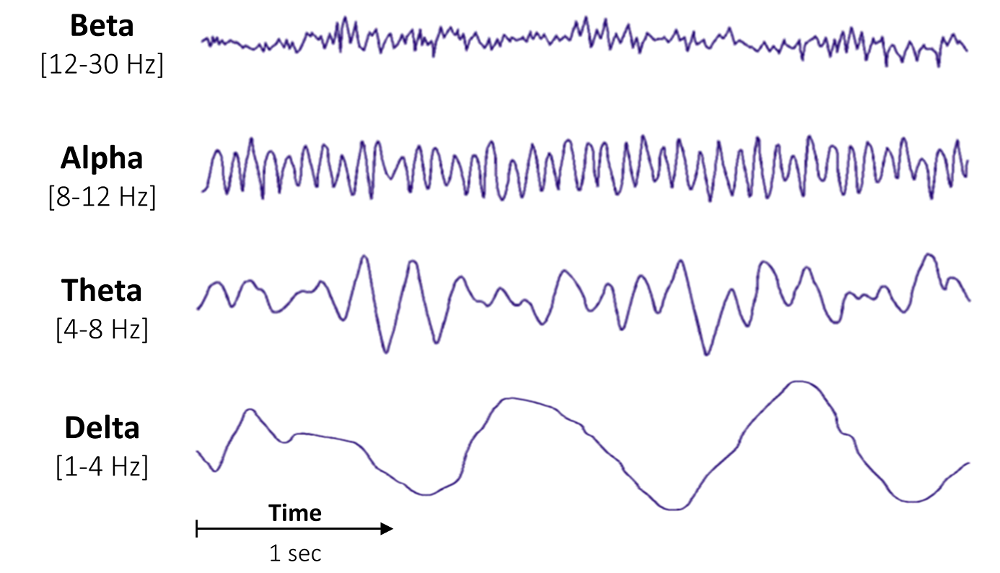

Note that a higher frequency is generally associated with lower signal amplitude over time. Waves at higher frequencies characterize states of wakefulness or concentration, while low frequencies are typical of states of relaxation or sleepiness. 

To analyze the single frequency components, the decomposition of the EEG signal is needed. It is commonly achieved through Fourier transforms. The most widely used algorithm to compute the Fourier transform is the Fast Fourier Transform (FFT), which returns, for each frequency bin, a complex number from which one can then easily extract the amplitude and phase of the signal at that specific frequency. The most straightforward method to calculate an estimate of the power spectral density of a random signal is by taking the magnitude-squared of the FFT, known as the direct method or "raw" periodogram. In spectral analysis of EEG data, this is typically  expressed in (micro)-Volts^2 per Hertz.

Following are the stages we experience during a restful night's sleep:

- Wake (W), during which alpha and beta waves are present, with predominance of beta.

- Stage 1 (N1), during which there is a transition from alpha to theta waves.

- Stage 2 (N2), during which there is a predominance of theta waves, with the appearance of  short delta waves.

- Stage 3 (N3), which is the deepest sleep phase and has a predominance of slow delta waves.

- REM, knwon as the 'dreaming phase',  which presents EEG characteristics very similar to the W phase.

Even though there are a number of ways to analyse the power spectral density for sleep study, in this Lab we rely on the **average band power**. This method generates a single value that describes the contribution of the specified frequency band with respect to the signal's total power.

Because it makes it possible to distinguish between the various stages of sleep, the average band power is a important parameter for sleep research. For instance, slow waves with a frequency range of 0.5 to 4 Hz (also known as the delta band), which represent synchronized brain activity, play a large role during deep sleep. In contrast, wakefulness is characterized by significantly greater higher-frequency activity and relatively little delta activity. Therefore, computing the delta band power for deep sleep and wakefulness, we would find two completely different values: the former would be quite high and the latter very low.

An example of typical recordings during sleep phases are provided in the picture below for brain (Fz and Cz), ocular (EOG) and muscular (EMG) activity

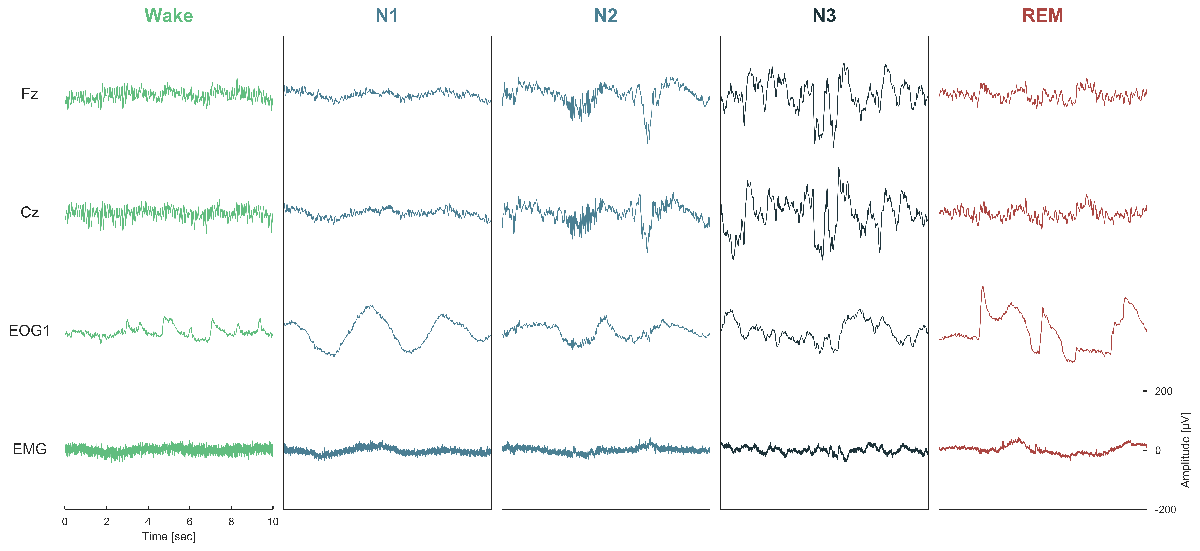

Observe how, as we go into deeper and deeper sleep, the EEG signal is characterized by increasingly slower and ampler waves. The REM phase is an exception, resulting more like wakefulness than deep sleep. 

## Assignment 1 - Data loading and visualization

The data is extracted from a real slow-wave sleep from one young individual. The duration is 30 seconds. The sampling frequency is 100 Hz and the channel name is F3. 

**QUESTION 1a**

Load the data stored in the mat file "EEG_data.mat". The file contains the EEG singal itself and the sampling frequnecy. Plot the signal against time, being careful to define the time vector correctly. What can you infer about the signal from your plot by examining it in the time domain?

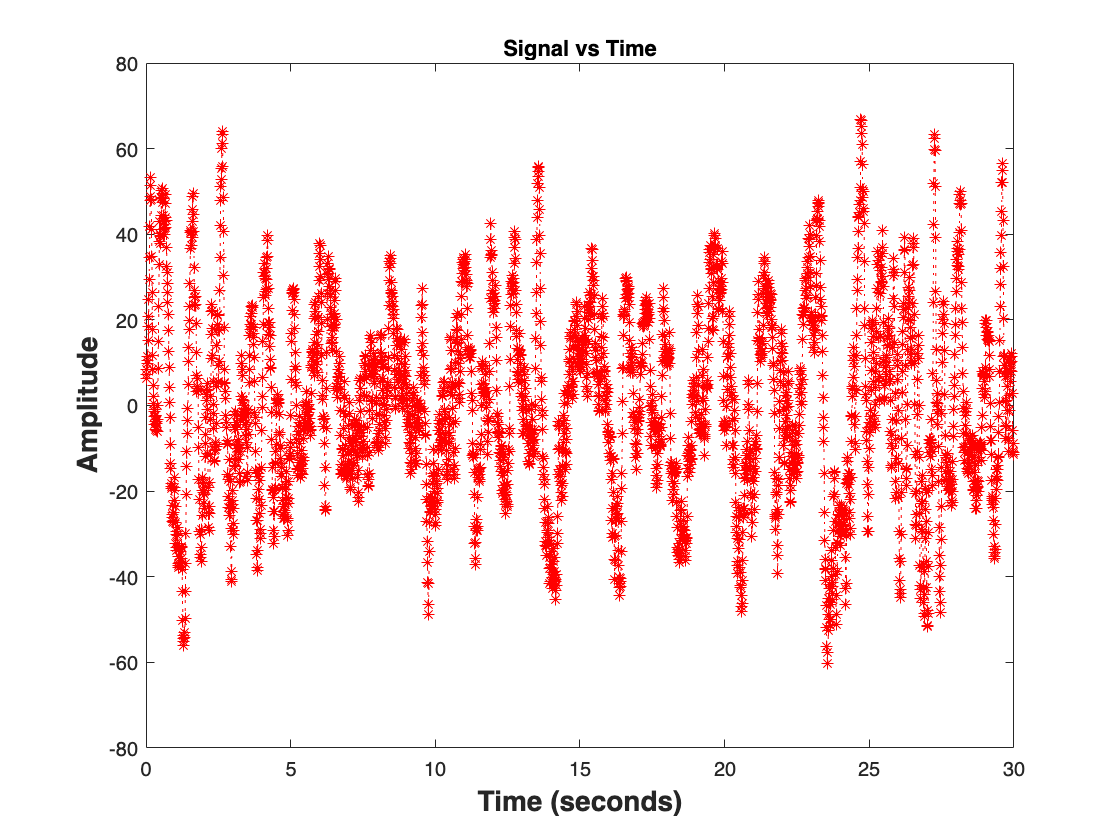

% clear all
% close all
% clc
% 
%------------------------------------------------
% Load the signal, define the time vector and EEG signal against time 
%------------------------------------------------
load('EEG_data.mat');

% Define the time vector
time = (0:length(EEG)-1)/fs;

% Plot the signal against time
plot(time, EEG,'LineStyle',':','Color','r','Marker','*');
xlabel('Time (seconds)','FontSize', 14, 'FontWeight', 'Bold');
ylabel('Amplitude','FontSize', 14, 'FontWeight', 'Bold');
title('Signal vs Time');

**ANSWER**

The amplitude of signal varies btween approximately -60 and 60. And the signal appears to contain some noise or high frequecy conponents.

## Assignment 2 - **Computing the power spectral density: Welch's method**

We must first estimate the power spectral density of the signal, in order to determine the average bandpower in the delta band. The most popular technique for doing this is the **Welch's periodogram**, a non-parametric estimation method, which involves averaging consecutive Fourier transforms of narrow windows, either with or without overlap. We call it the Bartlett approach if no overlapping is used.

The Welch’s approach, applied on a 30 seconds long EEG epoch, computes the periodogram on shorter segments and averages the results; in this ways it reduces the variance of the “raw” periodogram, computed on the entire signal. As EEG signals are constantly changing in time, it is exceedingly improbable that successive segments of the EEG signal will look exactly the same if the signal is divided into 30 s-long segments for analysis of EEG data. As a matter of fact, the raw periodogram assumes that each epoch is (wide-sense) stationary over the time period considered (which means that its first and second order statistics are constant in that period), but this is very unlikely with the EEG signal. By averaging the periodograms obtained over short segments, during which we can assume the signal to be stationary, the Welch's method permits reducing the variance. However, the **frequency and spectrum resolution suffer** as a result.

Any real (measured) signal can be defined as an infinite-length signal multiplied by a finite-length window. Considering the window as a rectangular one, it multiplies the signal by 1 inside the observation and by 0 outside. Regarding the spectral resolution, the capacity to distinguish between several spectral peaks decreases as the window length is decreased. Spectral resolution also depends on the type of window involved (rectangular, Hamming, Hann...) and is quantified by the width of the central lobe of the window spectrum. Differently, spectral leakage, which is connected to the development of false peaks in the spectral estimate, is related to the height of the side lobe. Considering both spectral resolution and leakage, different windows have different tradeoffs.

**QUESTION 2a**

If we want to achieve the highest spectral resolution, which window (type and length) should we use? Please motivate your answer.

**ASNWER**

Hamming Window

Regarding the frequency resolution, that is the step between two different frequency bins in the estimated spectrum, we can define it as:


$$F_{\textrm{res}} =\frac{F_s }{N}=\frac{F_s }{F_s t}=\frac{1}{t}$$


where Fs is the sampling frequency of the signal, N is the total number of samples and t is the duration, in seconds, of the signal. In other words, if we were to use the full length of our data (30 seconds), our final frequency resolution would be $\frac{1}{30}=0\ldotp 033$Hz, which is 30 frequency bins per Hertz. By using a 4-second sliding window, we reduce this frequency resolution to 4 frequency bins per Hertz, i.e., each step represents 0.25 Hz.

How do we define the optimal window duration then? A commonly used approach is to take a window sufficiently long to encompasses at least two full cycles of the lowest frequency of interest. In our case, our lowest frequency of interest is 0.5 Hz so we will choose a window of $\frac{2}{0\ldotp 5}=4$ seconds.

**QUESTION 2b**

Compute the power spectral density by Welch's method with window size of 4 seconds, and plot the obtained spectrum.

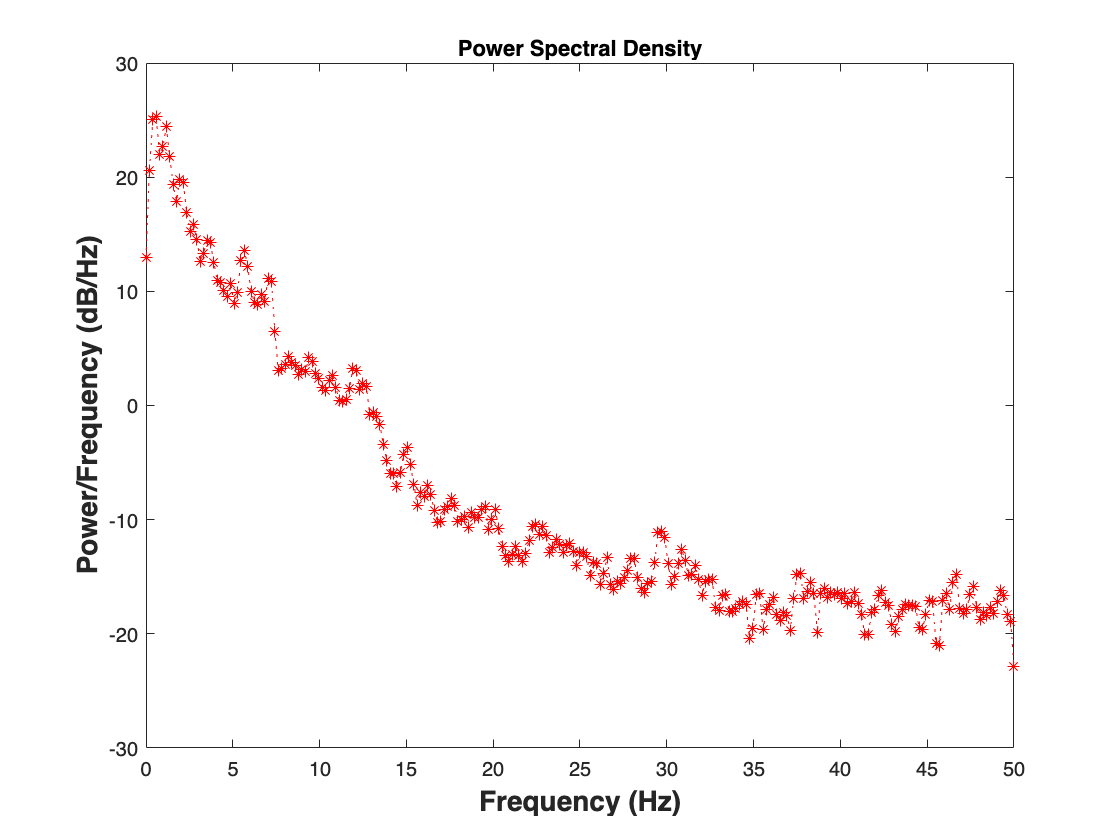

%------------------------------------------------
% Computing the power spectral density
%------------------------------------------------
% Define the signal data
x = EEG;

% Set the window size and overlap
window_size = 4 * fs;  % 4 seconds at a sampling frequency of 100 Hz
overlap = 0.5;  % 50% overlap

% Compute the number of samples per segment and the number of segments
nperseg = window_size;
noverlap = window_size * overlap;
nfft = 2^nextpow2(nperseg);
nsegments = floor((length(x) - noverlap) / (nperseg - noverlap));

% Compute the PSD using Welch's method
[Pxx, f] = pwelch(x, hamming(nperseg), noverlap, nfft, fs);


%------------------------------------------------
% Plot your results (with label, units, title)
%------------------------------------------------
plot(f, 10*log10(Pxx),'LineStyle',':','Color','r','Marker','*');
xlabel('Frequency (Hz)','FontSize', 14, 'FontWeight', 'Bold');
ylabel('Power/Frequency (dB/Hz)','FontSize', 14, 'FontWeight', 'Bold');
title('Power Spectral Density');

**QUESTION 2c**

Now, before computing the average delta bandpower, we need to find the frequency bins that intersect the delta frequency range.

Find the delta frequency range (0.5 - 4 Hz) from the power spectral desentiy obtained in b), and use MATLAB function 'area' to highlight where is the interested frquency range. 

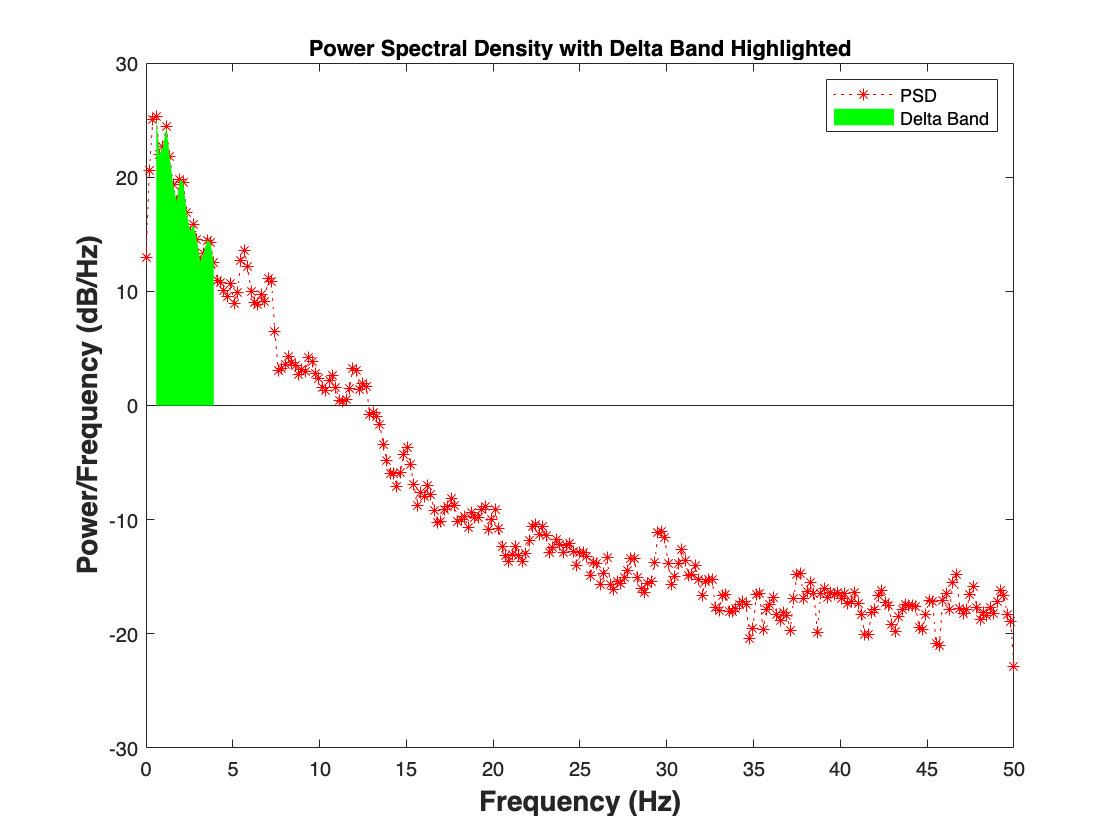

%------------------------------------------------
% Define lower and upper delta band limits
% Find intersecting values in frequency vector
%------------------------------------------------
% Define the frequency range of the PSD
freq_range = f;

% Find the indices of the frequency range that correspond to the delta band
delta_indices = find(freq_range >= 0.5 & freq_range <= 4);

% Extract the delta band power values from the PSD
delta_power = Pxx(delta_indices);


%------------------------------------------------
% Plot the power spectral density
% Highlight the delta frequency range (with label, units, title)
%------------------------------------------------
figure;
plot(freq_range, 10*log10(Pxx),'LineStyle',':','Color','r','Marker','*');
hold on;
area(freq_range(delta_indices), 10*log10(Pxx(delta_indices)), 'FaceColor', 'g', 'EdgeColor', 'none');
xlabel('Frequency (Hz)', 'FontSize', 14, 'FontWeight', 'Bold');
ylabel('Power/Frequency (dB/Hz)', 'FontSize', 14, 'FontWeight', 'Bold');
title('Power Spectral Density with Delta Band Highlighted');
legend('PSD', 'Delta Band');

**QUESTION 2d**

The absolute delta power is equal to the area defined in the previous plot.There is no closed-form formula to integrate this area, we need to approximate it. This is commonly achieved using the Trapezoidal rule. Display the result. 

HINT: Use MATLAB function *trapz*. 

%------------------------------------------------
% Calculate the absolute delta power, display your result with 'disp'
% function
%------------------------------------------------
% Compute the absolute delta power using the Trapezoidal rule
delta_power_abs = trapz(freq_range(delta_indices), Pxx(delta_indices));

% Display the result
fprintf('Absolute Delta Power: %.4f\n', delta_power_abs);

Absolute Delta Power: 297.6476


**QUESTION 2e**

In practice, rather than reporting the absolute band power, one may want to express the power in a frequency band as a percentage of the total power of the signal. This is called the relative band power. 

Calculate the relative delta power, and display your result. 

%------------------------------------------------
% Calculate the relative delta power and display your result 
%------------------------------------------------
% Compute the total power of the signal
total_power = trapz(freq_range, Pxx);

% Compute the relative delta power as a percentage of the total power
delta_power_rel = (delta_power_abs / total_power) * 100;

% Display the result
fprintf('Relative Delta Power: %.4f%%\n', delta_power_rel);

Relative Delta Power: 63.1367%


It is also very common to report the ratios between two frequency bands. For instance, the delta / beta ratio is a well-known index of slow-wave sleep quality. When computing ratios between two bands, it is important to control that the window length (4 seconds in this exercise) of the periodogram is the same for the two bands. 

%------------------------------------------------
% Calculate the Delta/beta ratio based on the absolute and relative power,
% display your result. 
%------------------------------------------------
% Define the frequency range of interest
delta_freq_range = [0.5 4];
beta_freq_range = [12 30];

% Find the indices of the frequency range that correspond to the delta and beta bands
delta_indices = find(freq_range >= delta_freq_range(1) & freq_range <= delta_freq_range(2));
beta_indices = find(freq_range >= beta_freq_range(1) & freq_range <= beta_freq_range(2));

% Extract the power values from the PSD for the delta and beta bands
delta_power = trapz(freq_range(delta_indices), Pxx(delta_indices));
beta_power = trapz(freq_range(beta_indices), Pxx(beta_indices));

% Compute the delta/beta ratio
delta_beta_ratio = delta_power / beta_power;

% Display the result
fprintf('Delta/Beta Ratio: %.4f\n', delta_beta_ratio);

Delta/Beta Ratio: 89.1063


**QUESTION 2f**

Why it is important to use the same window length when calculating the ratio between two frequency bands?

**ANSWER**

window length affects the resolution of the spectral analysis, and using different window lengths for different frequency bands can lead to inaccurate and misleading results.

## Assignment 3 - **Computing the power spectral density: **Blackman–Tukey** method**

In this assignment, we are going to implement the Blackman–Tukey method [Blackman and Tukey 1959] and compare it to the periodogram obtained by the Welch's method. 

The poor statistical quality of the periodogram estimator has been intuitively explained as arising from both the poor accuracy of the autocorrelation estimation for extreme lags ($\left|l\right|\approx N$), and the large number of (even if small) covariance estimation errors that are cumulatively summed up. 

**QUESTION 3a**

How does Blackman-Tukey method overcome the above-mentioned problem?

**ANSWER**

The Blackman-Tukey method overcomes the problem of poor statistical quality in the periodogram estimator by reducing the variance of the estimate by exploiting the structure of the autocorrelation function.

Instead of estimating the autocorrelation function directly, the Blackman-Tukey method first applies a window function to the data, which effectively smooths the signal and reduces the noise. Then, the method estimates the power spectral density by computing the Fourier transform of the windowed autocorrelation function.

By using a window function to smooth the signal before computing the autocorrelation function, the Blackman-Tukey method reduces the variance of the estimate and produces a more accurate estimate of the power spectral density compared to the periodogram estimator. This is because the window function effectively reduces the impact of extreme lags and minimizes the cumulatively summed covariance estimation errors.

**QUESTION 3b**

Calculate the absolute and relative delta power with Blackman-Tukey method, and compare its result with the result from Welch's method. What can you conclude?

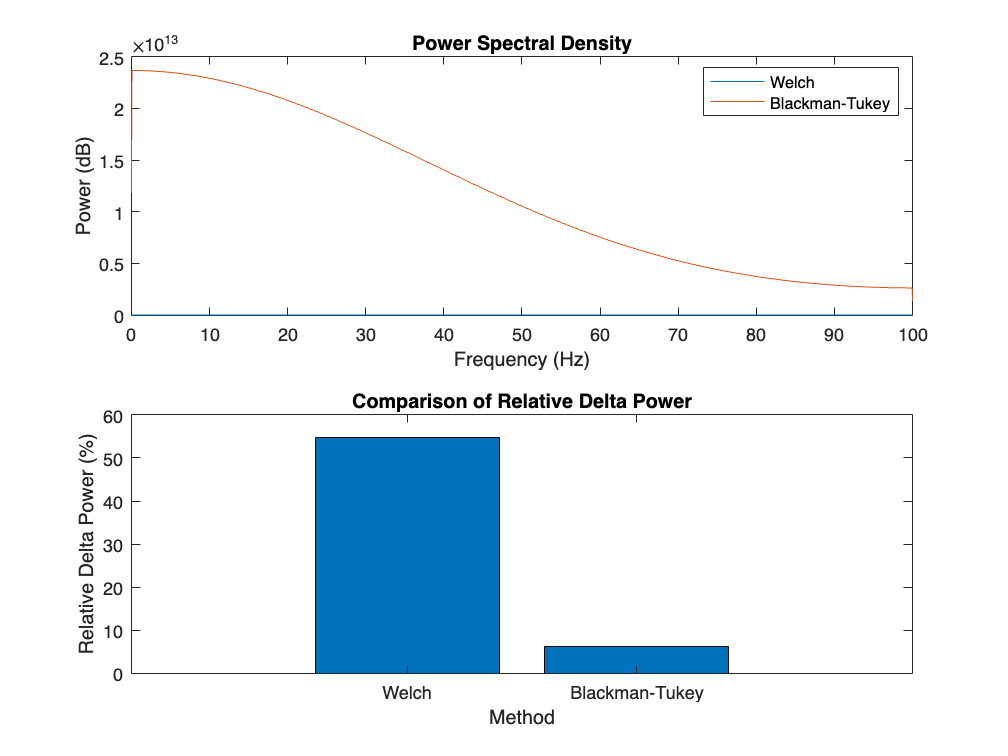

Fs = 200;
nfft = length(EEG);
window = hann(nfft);
[Pxx,F] = pwelch(EEG,window,[],nfft,Fs);
[Pxx_bt,F_bt] = pbt(EEG,window,[],nfft,Fs);
Pxx = Pxx';
F = F';
delta_freq_range = [1 4];
delta_power_welch = bandpower(Pxx,F,delta_freq_range,"psd");
delta_power_bt = bandpower(Pxx_bt,F_bt,delta_freq_range,"psd");
total_power_welch = bandpower(Pxx,F,"psd");
total_power_bt = bandpower(Pxx_bt,F_bt,"psd");
relative_delta_power_welch = delta_power_welch/total_power_welch*100;
relative_delta_power_bt = delta_power_bt/total_power_bt*100;

% Plot the results
figure;
subplot(2,1,1);
plot(F,Pxx); % Welch's method
hold on;
plot(F_bt,Pxx_bt); % Blackman-Tukey method
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Welch','Blackman-Tukey');
title('Power Spectral Density');
subplot(2,1,2);
bar([relative_delta_power_welch, relative_delta_power_bt]); % Bar graph of delta power
xlabel('Method');
ylabel('Relative Delta Power (%)');
set(gca,'XTickLabel',{'Welch','Blackman-Tukey'});
title('Comparison of Relative Delta Power');

**QUESTION 3c**

If the window length is M, the signal length is N, please express the resolution and variance of the Blackman-Tukey spectral estimator. What are the trade-offs between resolution and variance when selecting the window length. 

**ANSWER**

Short windows provide high resolution, but also high variance. This is because short windows provide limited information about the signal's autocorrelation function, leading to a higher degree of uncertainty in the spectral estimate.

Long windows provide low variance, but low resolution. This is because long windows provide more samples for estimating the autocorrelation function, leading to a more precise spectral estimate. However, long windows also introduce more smoothing, which reduces the resolution of the estimator.

## **Assignment 4: Parametric spectral estimation - AR model**

In this assignment, we will practice parametric spectrum estimation by simulating a signal's spectrum density function as an autoregressive (AR) process.

It is crucial to determine and choose a reasonable model order, before fitting the signal to any AR() model. The "optimal" order to model the signal can be determined using a variety of metrics, such as the Akaike information criterion (AIC) and the Bayesian information criterion (BIC).

**QUESTION 4a**

Now, we are going to find out what is the best order $p$ for the AR process to model the slow-wave sleep signal from the previous assignment with Yule-Walker's method and AIC as the criteria. Plot the AIC results versus corresponding order (use model orders from 50 to 200), and plot the spectrum with the selected 'best' order.

HINT: Use Matlab functions *ar* and *aic*, to find the best model order. Function *pyulear* is useful to generate the spectrum with the best order selected. Read the documentation to undestrand how to use them.

NOTE: This section may require some time to run. 

%------------------------------------------------
% Evaluate the Akaike Information Criteria for different model orders, with Yule-Walker's approach. 
% Plot the result and identify the best model order. 
%------------------------------------------------
% your code goes here (~10 lines of code)
% Define model order range
p = 50:200;

% Preallocate AIC results
aicc = zeros(size(p));

% Calculate AIC for each model order
for i = 1:length(p)
    i
    [sys, e] = ar(EEG, p(i), "yw");
    aicc(i) = aic(sys, "AIC");
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

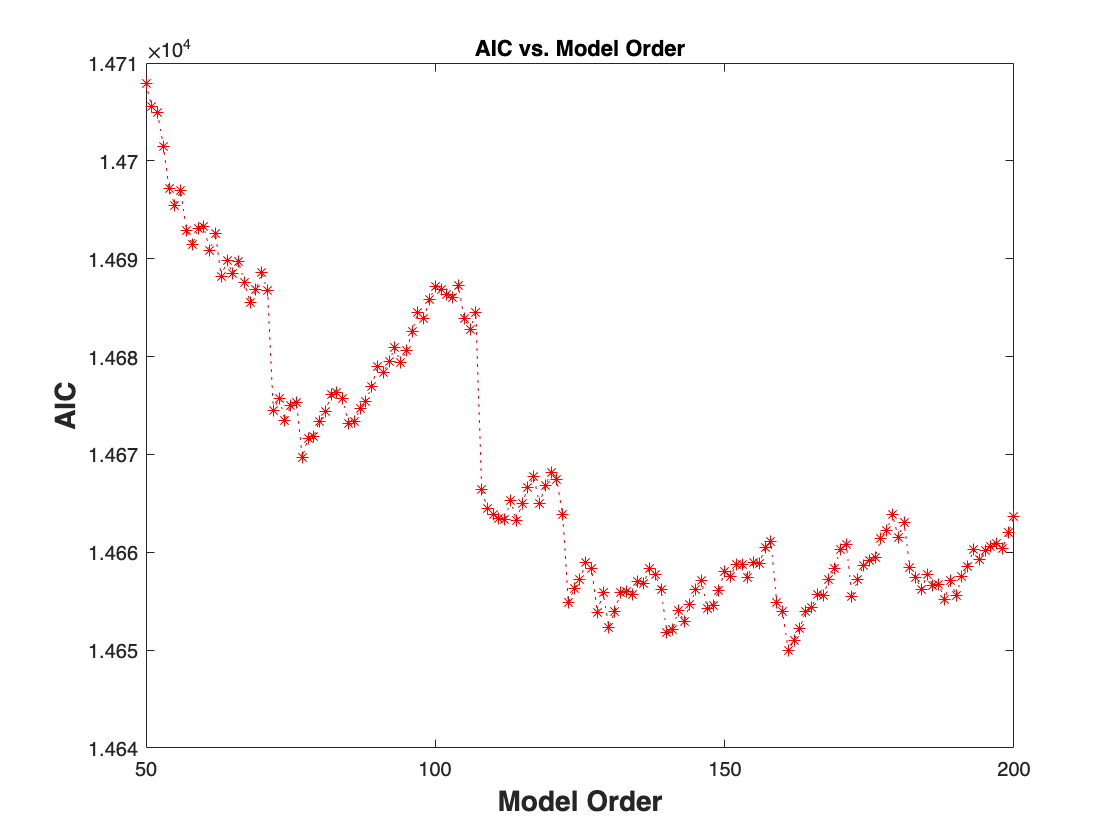

%------------------------------------------------
% Extract the spectrum with the selected model order and plot it
%------------------------------------------------
% your code goes here (~5 lines of code)
figure;
plot(p, aicc, 'LineStyle',':','Color','r','Marker','*');
title('AIC vs. Model Order');
xlabel('Model Order','FontSize', 14, 'FontWeight', 'Bold');
ylabel('AIC','FontSize', 14, 'FontWeight', 'Bold');

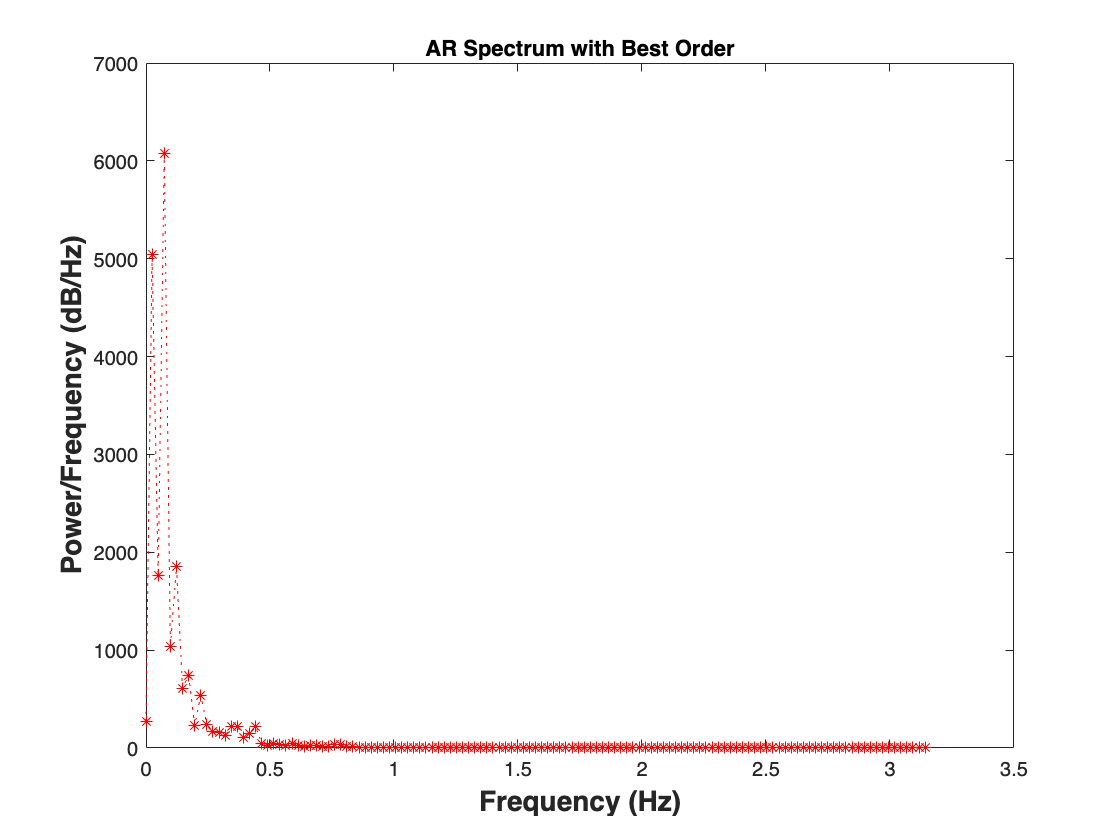


% Find the best order with minimum AIC
[~, idx] = min(aicc);
best_order = p(idx);

% Calculate spectrum with best order
[pxx, w] = pyulear(EEG, best_order);

% Plot spectrum
figure;
plot(w, pxx, 'LineStyle',':','Color','r','Marker','*');
title('AR Spectrum with Best Order');
xlabel('Frequency (Hz)','FontSize', 14, 'FontWeight', 'Bold');
ylabel('Power/Frequency (dB/Hz)','FontSize', 14, 'FontWeight', 'Bold');

**QUESTION 4b**

Do you think you would get much better results if you try to estimate the spectrum with a much greater order, such as p = 600? Do you think you would choose to fit the data with such a high order?

**ANSWER**

It is possible that using a much greater order, such as p = 600, could result in a slightly better fit of the data to the AR process, and therefore a slightly better estimate of the spectrum. However, there is also a risk of overfitting the data and introducing additional noise or variability into the model. Additionally, using a higher order would increase the computational complexity and time required for the model to run, which could be a limiting factor depending on the resources available. Ultimately, the choice of model order should strike a balance between model fit and model complexity, and should be based on careful evaluation of various model order selection criteria, such as the AIC and BIC, and on the specific requirements and constraints of the analysis.

**QUESTION 4c**

What could be a possible reason why we need a high model order?

**ANSWER: **

One possible reason why we need a high model order is that the signal may have complex dynamics that cannot be accurately modeled by a low-order AR process. The high-order model can capture the finer details of the signal, resulting in a more accurate representation of the spectrum. However, using too high of a model order can lead to overfitting and may not be necessary, so it is essential to balance the model's complexity with its accuracy.

## **Assignment 5: Comparison between parametric and non-paramteric spectrum estimation**

We have learned how to implement both parametric and non-parametric spectrum estimation. Now, we are going to compare which methods perform more accurate by using multiple experiments. *EEG_assigment_5-6.mat* file contains:

- **x:** The data for a single EEG pair sampled at 100Hz, and divided into epochs (sections) of 30 seconds. 

- **Labels: **Labels to the epochs in **x** which define the sleep stage: 0 = W(ake),  1 = N1, 2 = N2, 3 = N3 (Deep sleep), 4 = R (EM).

- **fs: **Sampling frequency (100 Hz) 

**QUESTION 5a**

Upload file. Select the first 50 epochs classified as deep sleep (labels = 3) and the first 50 classified otherwise (labels $\not= 3$; from now on we will call it "non-deep sleep"). 

Plot the power spetral density of an epoch labeled as deep sleep and one relative to an epoch labeled as non-deep sleep. Use the method you preder to extract the PSD estimations. Do you see any difference?

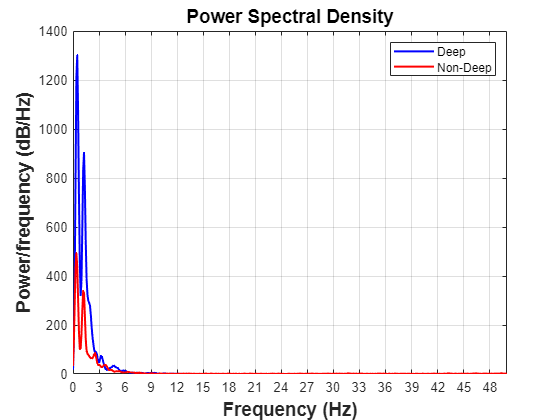

% ---------------------------------------------
% Load and select 50 epochs of deep sleep and 50 epochs of non-deep sleep.
% --------------------------------------------
% Your code goes here (~8 lines of code)
clc
clear all
load('EEG_assignment5-6.mat');
deep_sleep_data = x(labels == 3,:);
non_deep_sleep_data = x(labels ~= 3,:);
deep_sleep_data = deep_sleep_data(1:50,:);
non_deep_sleep_data = non_deep_sleep_data(1:50,:);

window_size = 4 * fs; % 4 seconds at 'Fs'
overlap = window_size / 2;
FFTsize=1024;


deep_sleep_epoch = deep_sleep_data(20,:);
non_deep_epoch = non_deep_sleep_data(20,:);

% extract the PSD estimation using pwelch function
[PSD_deep, frequency_deep] = pwelch(deep_sleep_epoch, window_size, overlap, FFTsize, fs);
[PSD_non_deep, frequency_non_deep] = pwelch(non_deep_epoch, window_size, overlap, FFTsize, fs);

% ---------------------------------------------
% Plot two PSD estimations.
% --------------------------------------------
% Your code goes here (~5 lines of code)
figure;
plot(frequency_deep, PSD_deep,'b','LineWidth',1.5);
hold on
plot(frequency_non_deep, PSD_non_deep,'r','LineWidth',1.5);
grid on
title('Power Spectral Density', 'FontSize', 14, 'FontWeight', 'Bold');
xlabel('Frequency (Hz)', 'FontSize', 14, 'FontWeight', 'Bold')
ylabel('Power/frequency (dB/Hz)', 'FontSize', 14, 'FontWeight','Bold')
legend('Deep','Non-Deep')
xticks(-length(frequency_deep):3:length(frequency_non_deep));

**ANSWER**

The PSD plot of the deep sleep epoch shows a higher power at frequencies between 0-15Hz, while the PSD plot of the non-deep sleep epoch shows a higher power at frequencies higher than 15Hz. 

**QUESTION 5b**

Apply non-paramteric spectrum estimation (Welch's method) to each epoch (both deep and non-deep sleep). For all epoch, calculate the corresponding delta/beta ratio. Compute mean and standard deviation of the estimation among deep sleep epochs and non-deep sleep epochs.  Represent the results as you consider appropriate.

% -------------------------------------------------------------------------
% Repeat what you did for assignment 2, but this time, you need to estimate
% for all 100 epochs. 
% Compute mean and standard deviation of delta/beta ratio among all epochs
% for deep sleep and non-deep sleep.
% ------------------------------------------------------------------------
%Your code goes here (~15 lines)

% Define frequency range of interest for delta and beta bands
beta_frequency_range = (frequency_deep >= 12 & frequency_deep <= 30);
delta_frequency_range = (frequency_deep >= 0.5 & frequency_deep <= 4);

num_epochs = size(deep_sleep_data, 1);
deep_ratio = zeros(num_epochs, 1);
non_deep_ratio = zeros(num_epochs, 1);

for i = 1:num_epochs
    % Calculate power spectral density (PSD) using Welch's method for deep sleep epoch
    [psd_deep, frequency_deep] = pwelch(deep_sleep_data(i,:), window_size, overlap, FFTsize, fs);
    abs_delta_p = trapz(frequency_deep(delta_frequency_range), psd_deep(delta_frequency_range));
    abs_beta_p = trapz(frequency_deep(beta_frequency_range), psd_deep(beta_frequency_range));
    deep_ratio(i) = abs_delta_p / abs_beta_p;

    % Calculate power spectral density (PSD) using Welch's method for non-deep sleep epoch
    [psd_non_deep, f_non_deep] = pwelch(non_deep_sleep_data(i,:), window_size, overlap, FFTsize, fs);
    abs_delta_p = trapz(f_non_deep(delta_frequency_range), psd_non_deep(delta_frequency_range));
    abs_beta_p = trapz(f_non_deep(beta_frequency_range), psd_non_deep(beta_frequency_range));
    non_deep_ratio(i) = abs_delta_p / abs_beta_p;
end

% Calculate mean and standard deviation of delta/beta ratio for deep sleep and non-deep sleep
deep_mean_ratio = mean(deep_ratio)

deep_mean_ratio = 104.1404

deep_std_ratio = std(deep_ratio)

deep_std_ratio = 47.9148

non_deep_mean_ratio = mean(non_deep_ratio)

non_deep_mean_ratio = 30.7739

non_deep_std_ratio = std(non_deep_ratio)

non_deep_std_ratio = 13.7987

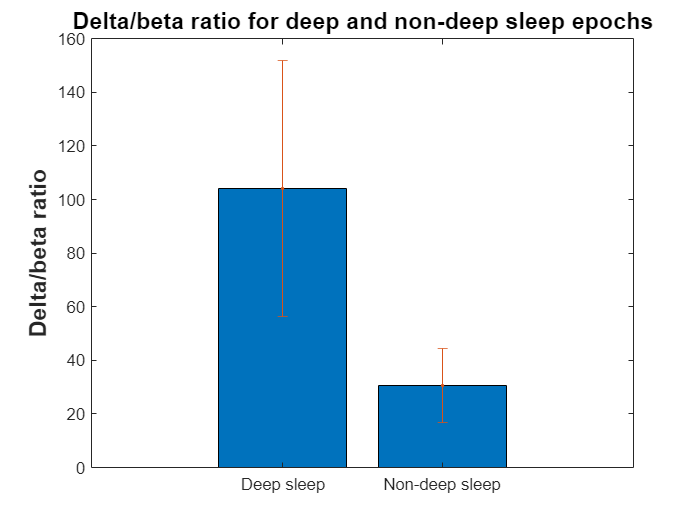


% Plot bar chart with error bars to compare delta/beta ratio between deep and non-deep sleep
figure();
bar([1 2], [deep_mean_ratio, non_deep_mean_ratio]);
hold on;
errorbar([1 2], [deep_mean_ratio, non_deep_mean_ratio], [deep_std_ratio, non_deep_std_ratio], '.');
xticklabels({'Deep sleep', 'Non-deep sleep'});
ylabel('Delta/beta ratio', 'FontSize', 14, 'FontWeight', 'Bold');
title('Delta/beta ratio for deep and non-deep sleep epochs', 'FontSize', 14, 'FontWeight', 'Bold');

**QUESTION 5c**

Repeat the same task you did in assigment 5b, this time using parametric spectrum estimation: consider the 100 epochs selected (deep and non-deep sleep) and apply paramteric spectrum estimation to each epoch. Calculate the corresponding delta/beta ratio, and compute the standard deviation and mean of the estimation among deep sleep and non-deep sleep epochs.

NOTE: In principle, it would be appropriate to estimate the best model order for each of the 100 epochs to be examined, repeating the process carried out in assignment 4a for each one. For a matter of simplicity here you can use the same model order you previously estimeted.

% -------------------------------------------------------------------------
% Repeat what you did for assignment 4, but this time, you need to estimate
% for all 100 epochs. 
% Compute mean and standard deviation of delta/beta ratio among all epochs
% for deep sleep and non-deep sleep.
% ------------------------------------------------------------------------
%Your code goes here (~15 lines)
% Define frequency range of interest for delta and beta bands
num_epochs = size(deep_sleep_data, 1);
deep_ratio_ar = zeros(num_epochs, 1);
non_deep_ratio_ar = zeros(num_epochs, 1);

my_order = 112;


for i = 1:num_epochs
    % Calculate power spectral density (PSD) using Yule-Walker method for deep sleep epoch
    [psd_deep, frequency_deep] = pyulear(deep_sleep_data(i,:), my_order, FFTsize, fs);
    abs_delta_p = trapz(frequency_deep(delta_frequency_range), psd_deep(delta_frequency_range));
    abs_beta_p = trapz(frequency_deep(beta_frequency_range), psd_deep(beta_frequency_range));
    deep_ratio_ar(i) = abs_delta_p / abs_beta_p;

    % Calculate power spectral density (PSD) using Yule-Walker method for non-deep sleep epoch
    [psd_non_deep, f_non_deep] = pyulear(non_deep_sleep_data(i,:), my_order, FFTsize, fs);
    abs_delta_p = trapz(f_non_deep(delta_frequency_range), psd_non_deep(delta_frequency_range));
    abs_beta_p = trapz(f_non_deep(beta_frequency_range), psd_non_deep(beta_frequency_range));
    non_deep_ratio_ar(i) = abs_delta_p / abs_beta_p;
end

% Calculate mean and standard deviation of delta/beta ratio for deep sleep and non-deep sleep
deep_mean_ratio_ar = mean(deep_ratio_ar)

deep_mean_ratio_ar = 100.8725

deep_std_ratio_ar = std(deep_ratio_ar)

deep_std_ratio_ar = 45.4949

non_deep_mean_ratio_ar = mean(non_deep_ratio_ar)

non_deep_mean_ratio_ar = 28.8861

non_deep_std_ratio_ar = std(non_deep_ratio_ar)

non_deep_std_ratio_ar = 12.8946

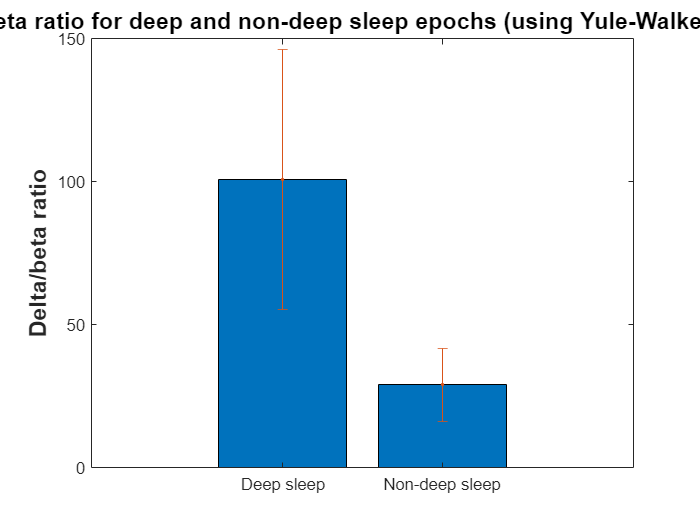


% Choose the best way to represent the results
figure();
bar([1 2], [deep_mean_ratio_ar, non_deep_mean_ratio_ar]);
hold on;
errorbar([1 2], [deep_mean_ratio_ar, non_deep_mean_ratio_ar], [deep_std_ratio_ar, non_deep_std_ratio_ar], '.');
xticklabels({'Deep sleep', 'Non-deep sleep'});
ylabel('Delta/beta ratio', 'FontSize', 14, 'FontWeight', 'Bold');
title('Delta/beta ratio for deep and non-deep sleep epochs (using Yule-Walker method)', 'FontSize', 14, 'FontWeight', 'Bold');

**QUESTION 5d**

Compare the results from 5b and 5c, which method performs more accurate, why?

**ANSWER**

 5c method may provide more accurate estimates of the delta/beta ratio across different epochs. Because it results in less variance compared to the Welch method. This may be due to the fact that parametric spectral estimation models the data with a known model order and eliminates the effects of windowing and averaging that can introduce more variance in the Welch method.

## **Assignment 6: Detection theory**

In this assignment we will apply detection theory to find the threshold between the Delta/Beta ratio obtained from the deep sleep signals '**x_N3**' and the Delta/Beta ration obtained from the sleep signals in other phases '**x_other**' extracted in assignment 5a. **This time we use all epochs.**

**QUESTION 6a**

Calulate the mean Delta/Beta ratio and the standard deviation, over all epochs, for deep sleep signals and signals in other phases seperately (as in Assignment 2e). Plot the obtained values for Delta/Beta ratio over epochs, and draw lines of mean and standard deviation on the same figure. Tip: store the values of the Delta/Beta ratio per epoch in vectors, for deep sleep and other phases, since you will need it for the next question.

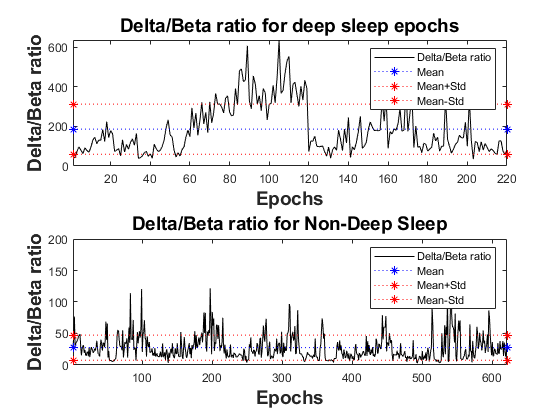

% --------------------------------------------------------------------------
% Calculate the Delta/beta ratio based on the absolute power of the deep
% sleep signals, for all epochs (similar logic to 5b)
% --------------------------------------------------------------------------

% Your code goes here
% ----------------------------------------------------------------------------
% Calculate the Delta/beta ratio based on the absolute power of the other
% sleep signals, for all epochs (similar logic to 5b)
% ----------------------------------------------------------------------------
% Your code goess here
% -------------------------------------------------------------------------
% Choose the best way to represent the results
% ------------------------------------------------------------------------
%Your code goes here (~5 lines)
clc
clear all
load('EEG_assignment5-6.mat');

deep_sleep_data = x(labels == 3,:);
non_deep_sleep_data = x(labels ~= 3,:);


window_size = 4 * fs; % 4 seconds at 'Fs'
overlap = window_size / 2;
FFTsize=1024;


num_epochs_deep = size(deep_sleep_data, 1);
num_epochs_non = size(non_deep_sleep_data, 1);
deep_ratio = zeros(num_epochs_deep, 1);
non_deep_ratio = zeros(num_epochs_non, 1);


for i = 1:num_epochs_deep
    % Calculate power spectral density (PSD) using Welch's method for deep sleep epoch
    [psd_deep, frequency_deep] = pwelch(deep_sleep_data(i,:), window_size, overlap, FFTsize, fs);
    beta_frequency_range = (frequency_deep >= 12 & frequency_deep <= 30);
    delta_frequency_range = (frequency_deep >= 0.5 & frequency_deep <= 4);
    abs_delta_p = trapz(frequency_deep(delta_frequency_range), psd_deep(delta_frequency_range));
    abs_beta_p = trapz(frequency_deep(beta_frequency_range), psd_deep(beta_frequency_range));
    deep_ratio(i) = abs_delta_p / abs_beta_p;
end


for i = 1:num_epochs_non
    % Calculate power spectral density (PSD) using Welch's method for non-deep sleep epoch
    [psd_non_deep, f_non_deep] = pwelch(non_deep_sleep_data(i,:), window_size, overlap, FFTsize, fs);
    beta_frequency_range = (f_non_deep >= 12 & f_non_deep <= 30);
    delta_frequency_range = (f_non_deep >= 0.5 & f_non_deep <= 4);
    abs_delta_p = trapz(f_non_deep(delta_frequency_range), psd_non_deep(delta_frequency_range));
    abs_beta_p = trapz(f_non_deep(beta_frequency_range), psd_non_deep(beta_frequency_range));
    non_deep_ratio(i) = abs_delta_p / abs_beta_p;
end


% Plot results
figure;
subplot(2,1,1);
plot(deep_ratio, 'k');
hold on;
line([1 length(deep_ratio)], [mean(deep_ratio) mean(deep_ratio)], 'LineStyle',':','Color','b','Marker','*');
line([1 length(deep_ratio)], [mean(deep_ratio)+std(deep_ratio) mean(deep_ratio)+std(deep_ratio) ], 'LineStyle',':','Color','r','Marker','*');
line([1 length(deep_ratio)], [mean(deep_ratio)-std(deep_ratio)  mean(deep_ratio)-std(deep_ratio)], 'LineStyle',':','Color','r','Marker','*');
title('Delta/Beta ratio for deep sleep epochs', 'FontSize', 14, 'FontWeight', 'Bold');
xlim([1 length(deep_ratio)])
xlabel('Epochs', 'FontSize', 14, 'FontWeight', 'Bold');
ylabel('Delta/Beta ratio', 'FontSize', 14, 'FontWeight', 'Bold');
legend('Delta/Beta ratio', 'Mean', 'Mean+Std', 'Mean-Std');
subplot(2,1,2);
plot(non_deep_ratio, 'k');
hold on;
line([1 length(non_deep_ratio)], [mean(non_deep_ratio) mean(non_deep_ratio)], 'LineStyle',':','Color','b','Marker','*');
line([1 length(non_deep_ratio)], [mean(non_deep_ratio)+std(non_deep_ratio) mean(non_deep_ratio)+std(non_deep_ratio)], 'LineStyle',':','Color','r','Marker','*');
line([1 length(non_deep_ratio)], [mean(non_deep_ratio)-std(non_deep_ratio) mean(non_deep_ratio)-std(non_deep_ratio)], 'LineStyle',':','Color','r','Marker','*');
xlim([1 length(non_deep_ratio)])
title('Delta/Beta ratio for Non-Deep Sleep', 'FontSize', 14, 'FontWeight', 'Bold');
xlabel('Epochs', 'FontSize', 14, 'FontWeight', 'Bold');
ylabel('Delta/Beta ratio', 'FontSize', 14, 'FontWeight', 'Bold');
legend('Delta/Beta ratio', 'Mean', 'Mean+Std', 'Mean-Std');

**QUESTION 6b**

Plot a histogram of the obtained Delta/Beta ratio, for all epochs, for deep sleep and non-deep sleep. Then, try to fit a distribution to the histogram by using MATLAB function 'histfit'. 

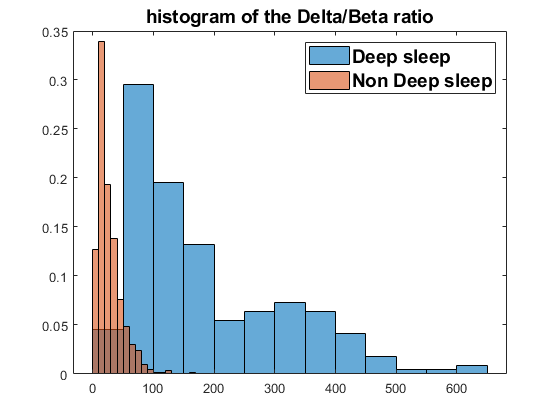

% ------------------------------------------------------------------------------
% Plot a histogram of the Delta/Beta ratio obatined from the deep sleep and
% the other signals
% -------------------------------------------------------------------------------
% Your code goes here


close all
figure;
histogram(deep_ratio, 'Normalization', 'probability');
hold on;
histogram(non_deep_ratio, 'Normalization', 'probability');
legend('Deep sleep', 'Non Deep sleep','FontSize', 14, 'FontWeight', 'Bold')
title('histogram of the Delta/Beta ratio','FontSize', 14, 'FontWeight', 'Bold')

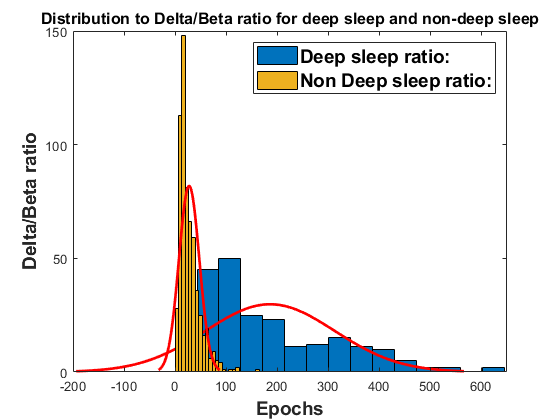


figure;
histfit(deep_ratio)
hold on
histfit(non_deep_ratio)
hold off
legend('Deep sleep ratio: ','','Non Deep sleep ratio: ','FontSize', 14, 'FontWeight', 'Bold')
xlabel('Epochs', 'FontSize', 14, 'FontWeight', 'Bold');
ylabel('Delta/Beta ratio', 'FontSize', 14, 'FontWeight', 'Bold');
title('Distribution to Delta/Beta ratio for deep sleep and non-deep sleep', 'FontSize', 12, 'FontWeight', 'Bold');

The curve that fits the distribution of data is the probability distribution function (PDF), which you can see in red with the 'histfit' plot. As you can notice, depending on your choice of distribution function, the PDF might not fit that well the data you have, i.e., your model might not be precise enough for certain applications. In the case of detection, 

The 'histfit' function uses 'fitdist' to obtain such PDF. Thus, you are also able to fit the distribution by using the MATLAB function 'fitdist', which will give you the identified distribution parameters. Use 'fitdist' to find the distribution model parameters and use the function 'pdf' to obtain the related PDF. Plot the PDFs for both deep sleep and non-deep sleep.

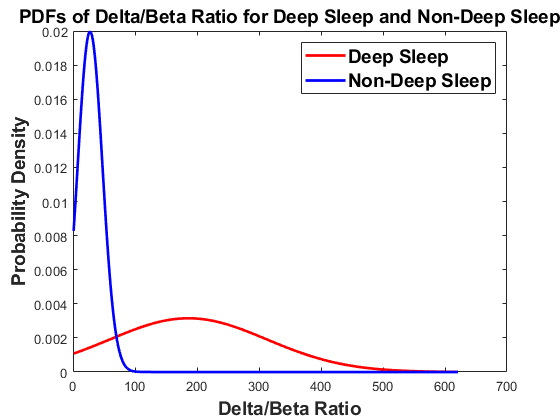

%----------------------------------------------------------------------
% Fit a distribution to each histogram with 'fitdist'. Use the same
% distributions you chose for 6b.
% ---------------------------------------------------------------------
% Your code goes here
% Fit a distribution to each histogram using fitdist
deep_sleep_dist = fitdist(deep_ratio, 'Normal');
non_deep_sleep_dist = fitdist(non_deep_ratio, 'Normal');
x = 1:length(non_deep_ratio);
deep_sleep_pdf = pdf(deep_sleep_dist, x);
non_deep_sleep_pdf = pdf(non_deep_sleep_dist, x);
plot(x, deep_sleep_pdf, 'r', 'LineWidth', 2)
hold on
plot(x, non_deep_sleep_pdf, 'b', 'LineWidth', 2)
hold off
legend('Deep Sleep', 'Non-Deep Sleep', 'FontSize', 14, 'FontWeight', 'Bold')
title('PDFs of Delta/Beta Ratio for Deep Sleep and Non-Deep Sleep', 'FontSize', 14, 'FontWeight', 'Bold')
xlabel('Delta/Beta Ratio', 'FontSize', 14, 'FontWeight', 'Bold')
ylabel('Probability Density', 'FontSize', 14, 'FontWeight', 'Bold')

**QUESTION 6c**

Now, we are trying to detect the deep sleep signals using receiver operating characteristic (ROC) curves. ROC curves are plots of the probability of detection (Pd), in this case, the probablity that an epoch belongs to deep sleep vs. the probability of false alarm (Pf). Calculate and plot the ROC curve based on the probablity distributions. Adittionally, plot together both distributions p(x|H1) and p(x|H0) to better visualize the problem, where x is the data, H1 is deep sleep and H0 is non-deep sleep.

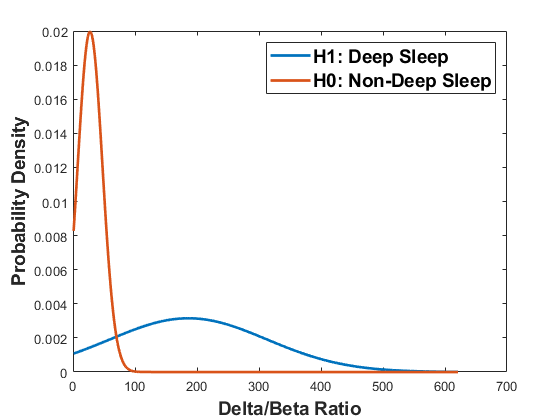

% ------------------------------------------------------------------------------
% Plot the distribution of x for H1 (deep sleep) and H0 (non-deep sleep) in the 
% same figure
% ------------------------------------------------------------------------------
% Your code goes here


% Plot the distribution of x for H1 (deep sleep) and H0 (non-deep sleep) in the same figure



% Define the x-values to evaluate the probability density functions
x_vals = 1:length(non_deep_ratio);

% Evaluate the probability density functions
pdf_H1 = pdf(deep_sleep_dist, x_vals);
pdf_H0 = pdf(non_deep_sleep_dist, x_vals);

% Plot the probability density functions
figure
plot(x_vals, pdf_H1, 'LineWidth', 2)
hold on
plot(x_vals, pdf_H0, 'LineWidth', 2)
xlabel('Delta/Beta Ratio', 'FontSize', 14, 'FontWeight', 'Bold')
ylabel('Probability Density', 'FontSize', 14, 'FontWeight', 'Bold')
legend('H1: Deep Sleep', 'H0: Non-Deep Sleep', 'FontSize', 14, 'FontWeight', 'Bold')

Notice that both distributions overlap, thus it is not possible to achieve a perfect classification of deep sleep vs non-deep sleep for this case.

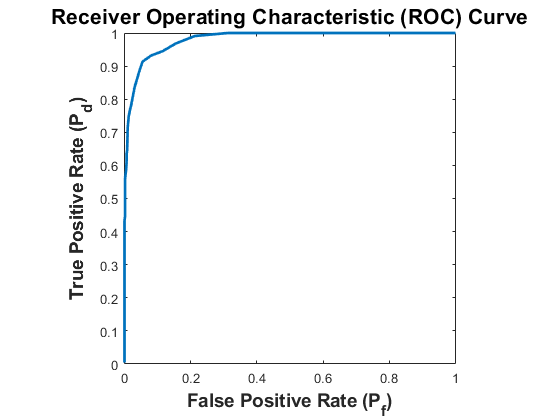

% --------------------------------------------------------------------------
% Calculte the ROC, you might want to use 'cdf' to compute the cumulative
% distribution function
% L = pdf_N3./pdf_other;
% --------------------------------------------------------------------------
% Your code goes here 


% Define a range of thresholds to evaluate
thresholds = linspace(min(x_vals), max(x_vals), 100);

% Initialize variables to store the true positive rate (TPR) and false positive rate (FPR)
TPR = zeros(size(thresholds));
FPR = zeros(size(thresholds));

% Calculate the TPR and FPR for each threshold
for i = 1:length(thresholds)
    % Calculate the probability of detection (TPR) and probability of false alarm (FPR) for the current threshold
    TPR(i) = sum(deep_ratio >= thresholds(i)) / length(deep_ratio);
    FPR(i) = sum(non_deep_ratio >= thresholds(i)) / length(non_deep_ratio);
end

% Plot the ROC curve
figure
plot(FPR, TPR, 'LineWidth', 2)
xlabel('False Positive Rate (P_{f})', 'FontSize', 14, 'FontWeight', 'Bold')
ylabel('True Positive Rate (P_{d})', 'FontSize', 14, 'FontWeight', 'Bold')
title('Receiver Operating Characteristic (ROC) Curve', 'FontSize', 16, 'FontWeight', 'Bold')
axis square

How can we see in the ROC curve that there is no perfect classification?

**ANSWER**

In an ideal scenario, a ROC curve would show a steep increase in the true positive rate (Pd) and a very low false positive rate (Pf), resulting in a curve that goes up to 1 on the y-axis and then to the right up to 1 on the x-axis, forming a sharp corner at the top left corner of the plot. This would indicate that the classification model is able to perfectly separate the two classes, in this case, deep sleep and non-deep sleep.

However, in the current scenario where the distributions overlap, it is not possible to achieve a perfect classification. This will be reflected in the ROC curve, where the curve will not show a sharp corner, but instead a curve that is more gradual, indicating that as the true positive rate (Pd) increases, the false positive rate (Pf) also increases. 

**QUESTION 6d**

In the end, we would like to find a threshold boundary which ensures a Pf of 0.1. Calculate that threshold and find out the corresponding Pd. 

Show the threshold value in the distribution plot (like question 6c), higlighting the areas that relate to Pf and Pd (see Figure 15.4 in the course reader).

% --------------------------------------------------------------------------
% Compute Pf and plot it
% --------------------------------------------------------------------------

% Your code goes here
% Compute Pf and plot it
Pd = cdf(deep_sleep_dist,x);
pf = 1-cdf(non_deep_sleep_dist,x);
plot(pf)
xlabel('Probability of false alarm (Pf)', 'FontSize', 14, 'FontWeight', 'Bold');
ylabel('CDF', 'FontSize', 14, 'FontWeight', 'Bold');
grid on;


% --------------------------------------------------------------------------
% Find the lambda and index that ensures a Pf of 0.1, and get the Pd value.
% HINT: remember that, since Pf is in the left side of the distribution plot
% (see 6c), you are interested in the right side of the tail of p(x|H0).
% --------------------------------------------------------------------------
% Your code goes here
[~, lambda] = min(abs(pf-0.1))

lambda = 53

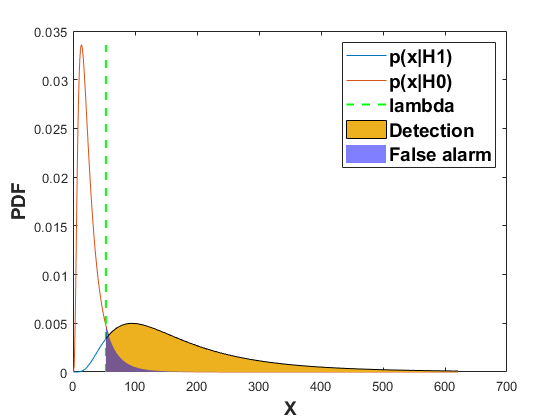

% --------------------------------------------------------------------------
% Plot both distributions p(x|H0) and p(x|H1) highlighting the area on the
% plot for Pf and Pd with the previously obtained lambda.
% --------------------------------------------------------------------------
% Your code goes here

close all
plot(deep_sleep_pdf)
hold on 
plot(non_deep_sleep_pdf)
line([lambda lambda], [0 max(pdf(non_deep_sleep_dist, x))], 'Color', 'g', 'LineStyle', '--', 'LineWidth', 1.5);

area(lambda:length(non_deep_ratio), deep_sleep_pdf(lambda:length(pf)));
area(lambda:x_vals, non_deep_sleep_pdf(lambda:x_vals))
xlabel('X', 'FontSize', 14, 'FontWeight', 'Bold'); 
ylabel('PDF', 'FontSize', 14, 'FontWeight', 'Bold');

x_shade = linspace(lambda, max(deep_ratio), 1000);
y_shade = pdf(non_deep_sleep_dist, x_shade);
area(x_shade, y_shade, 'FaceColor', 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none');

legend('p(x|H1)', 'p(x|H0)','lambda',  'Detection','False alarm','FontSize', 14, 'FontWeight', 'Bold')
hold off

**QUESTION 6e**

What are the consequences of choosing a lower value of lambda?

**ANSWER**

Choosing a lower value of lambda will result in a higher threshold for classification. This means that fewer epochs will be classified as belonging to deep sleep, leading to a higher probability of false negatives (missed deep sleep epochs) and a lower probability of true positives (correctly identified deep sle

function [Pxx,F] = pbt(x,window,noverlap,nfft,Fs)
% Blackman-Tukey method for power spectral density estimation
% Inputs:
%   x       - input signal
%   window  - window function
%   noverlap - number of samples to overlap between segments
%   nfft    - length of the fft
%   Fs      - sampling frequency
% Outputs:
%   Pxx     - power spectral density estimate
%   F       - frequency vector

% Calculate the autocorrelation function
[Rxx,lags] = xcorr(x,'biased');
Rxx = Rxx(lags>=0);
lags = lags(lags>=0);

% Apply the window function
W = fft(window,nfft);
Rxx = Rxx .* W(:).^2;

% Compute the power spectral density estimate
Pxx = abs(fft(Rxx,nfft)).^2 / (Fs*sum(window.^2));
Pxx = Pxx(1:nfft/2+1);
Pxx(2:end-1) = 2*Pxx(2:end-1);
F = (0:nfft/2)*(Fs/nfft);
end

ep epochs).